E.T.S. Ingeniería Informática  Grado en Ingeniería de la Salud 

Ampliación de Matemáticas     Curso 2023/24 

## Práctica evaluable

Considere el problema resuelto como tarea: 

                
$$\frac{\partial^2 u}{\partial t^2} = c^2 \frac{\partial^2 u}{\partial x^2}, \quad x \in [0,L], t\in [0,T_f] $$


                
$$u(x,0)=\frac{x}{L}+sin(c\cdot x), \quad \frac{\partial u}{\partial t}(x,0)=1, \quad x \in [0,L]$$


                
$$u(0,t)=t, \qquad t \in (0,T_f]$$


                
$$\frac{\partial u}{\partial x} (L,t)=\frac{1}{L}+\frac{c}{2} \left( cos(c(L+ct))+cos(c(L-ct)) \right) \, \qquad t \in (0,T_f]$$
		

Copie las funciones solExacta, DifFin y EleFin del fichero .mlx entregado en dicha tarea al final de este fichero.

Considere el problema con c=0.8, L=10, Tf=5. 

- Dibuja la solución exacta del problema.

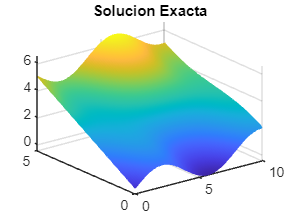

figure
c=0.8;
L=10;
Tf=5;
M=100;
N=1000;
[xex,tex,yex]=solExacta(c,L,Tf,M,N);

mesh(xex,tex,yex)
title('Solucion Exacta')

- Determina unos valores de M y N para los que el método de Diferencias finitas tenga problemas de estabilidad. ¿Cuánto vale $r=\frac{{\Delta t}^2 }{{\Delta x}^2 }$? 

        
$$\Delta x=\frac{L}{M}=0.1 \qquad
\Delta x^2 = 0.01\\
\Delta t = \frac{5}{N}=0.1667 \qquad
\Delta t^2=0.02778\\
r=\frac{\Delta t^2}{\Delta x^2}=2.778$$


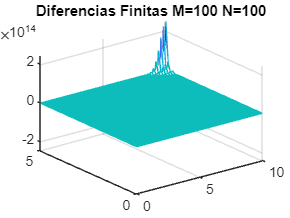

M=100;
N=30;

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

figure

mesh(xdf,tdf,ydf)
title('Diferencias Finitas M=100 N=100')

- Dibuja la solución que se obtiene con el método de DF y con el de EF y comenta los resultados obtenidos.

*        Cuando ambos métodos son estables tienen errores similares.*

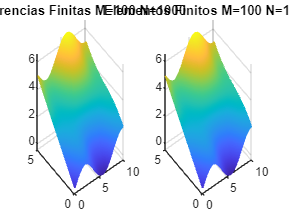

M=100;
N=1000;

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

figure

subplot(121)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas M=100 N=1000')

[xef,tef,yef]=EleFin(c,L,Tf,M,N);

subplot(122)
mesh(xef,tef,yef)
title('Elementos Finitos M=100 N=1000')

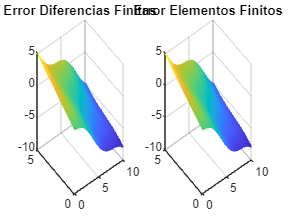


[yex]=solExacta(c,L,Tf,M,N);

figure
subplot(121)
mesh(xdf,tdf,ydf-yex);
title('Error Diferencias Finitas')
subplot(122)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos')

A partir de las funciones DifFin y EleFin escriba unas nuevas funciones DifFinDH y EleFinDH que determine de forma numérica la solución del problema obtenido cambiando la condición de contorno en x=0 por una  condición de contorno Dirichlet homogénea.

- Determina unos valores de M y N para los que DifFinDH no tenga problemas de estabilidad.¿Cuánto vale $r=\frac{{\Delta t}^2 }{{\Delta x}^2 }$? 

       * Podemos observar que la forma de la gráfica cambia al cambiar la CC.*

        
$$\Delta x=\frac{L}{M}=0.1 \qquad
\Delta x^2 = 0.01\\
\Delta t = \frac{5}{N}=0.125 \qquad
\Delta t^2=0.015625\\
r=\frac{\Delta t^2}{\Delta x^2}=1.5625$$


*        Probando con otros valores de N, como N=40 (estable) y N=35 (inestable), se observa que la estabilidad del método con la CC homogénea es (al menos aproximadamente) la misma que con las condiciones anteriores.*

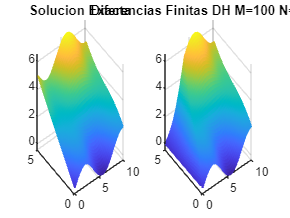

M=100;
N=40;

[xex,tex,yex]=solExacta(c,L,Tf,M,N);

[xdf,tdf,ydf]=DifFinDH(c,L,Tf,M,N);

figure
subplot(121)
mesh(xex,tex,yex)
title('Solucion Exacta')
subplot(122)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas DH M=100 N=1000')

- Dibuja la solución que se obtiene con DifFinDH y EleFinDH para esos valores de M y N y la diferencia entre los dos.

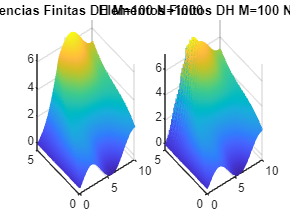

M=100;
N=1000;

figure

[xdf,tdf,ydf]=DifFinDH(c,L,Tf,M,N);
[xef,tef,yef]=EleFinDH(c,L,Tf,M,N);

subplot(121)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas DH M=100 N=1000')
subplot(122)
mesh(xef,tef,yef)
title('Elementos Finitos DH M=100 N=1000')

Comenta los resultados obtenidos.

*        En este caso podemos observar que con los valores de M y N elegidos, el método de Elementos Finitos comienza a ser inestable, si se reduce el valor de N más, se volverá aún más inestable perdiendo totalmente la forma de la gráfica. Esto implica que el método de Elementos Finitos es mucho más inestable que el de Diferencias Finitas en cuanto a valores de r se refiere, al menos en este caso, en el que se usa Euler Explícito.*

Firma (Nombre y Apellidos): Viktor Yosava Zinkovskyi

Una vez completados los apartados anteriores exporta el fichero con códigos y figuras incluidas a pdf y sube los dos ficheros (.mlx y .pdf) a campus virtual

FUNCIONES

% solExacta

function [x,t,y]=solExacta(c,L,Tf,M,N)

ax=L./M;
at=Tf/N;
x=0:ax:L;
t=0:at:Tf;
[X,TP]=meshgrid(x,t);
y=X/L+(sin(c*X+c^2*TP)+sin(c*X-c^2*TP))/2+TP;
end

% DifFin

function [x,t,y]=DifFin(c,L,Tf,M,N)

ax=L./M;
at=Tf/N;
r=at^2/ax^2;
x=0:ax:L;
t=0:at:Tf;
m=length(x);
n=length(t);
A=(2.-2*c^2*r)*eye(m-1)+r*c^2*diag(ones(m-2,1),1)+r*c^2*diag(ones(m-2,1),-1);
%length(A)
A(M,M-1)=2*A(M,M-1);
B=zeros(1,M);

y=zeros(n,m);
%length(y)
y(:,1)=t;
y(1,:)=x/L+sin(c*x);
y(2,:)=y(1,:)+at;

for j=2:N
    B(1,1)=c^2*r*t(j);
    B(1,M)=c^2*r*(2*ax/L+c*ax*(cos(c*L+c^2*t(j))+cos(c*L-c^2*t(j))));
    y(j+1,2:m)=(A*y(j,2:m)'-y(j-1,2:m)'+B')';

end

end

% DifFinDH

function [x,t,y]=DifFinDH(c,L,Tf,M,N)

ax=L./M;
at=Tf/N;
r=at^2/ax^2;
x=0:ax:L;
t=0:at:Tf;
m=length(x);
n=length(t);
A=(2.-2*c^2*r)*eye(m-1)+r*c^2*diag(ones(m-2,1),1)+r*c^2*diag(ones(m-2,1),-1);
%length(A)
A(M,M-1)=2*A(M,M-1);
B=zeros(1,M);

y=zeros(n,m);
%length(y)
y(:,1)=0; % Condición Dirichlet Homogénea
y(1,:)=x/L+sin(c*x);
y(2,:)=y(1,:)+at;

for j=2:N
    % B(1,1)=c^2*r*t(j); Lo comento por la Condición Dirichlet Homogénea
    B(1,M)=c^2*r*(2*ax/L+c*ax*(cos(c*L+c^2*t(j))+cos(c*L-c^2*t(j))));
    y(j+1,2:m)=(A*y(j,2:m)'-y(j-1,2:m)'+B')';

end

end

% EleFin

function [x,t,y]=EleFin(c,L,Tf,M,N)

ax=L/M;
at=Tf/N;
x=0:ax:L;
t=0:at:Tf;
m=length(x);
n=length(t);
c1=2./ax;
c2=-1./ax;
a1=2.*ax/3.;
a2=ax/6.;
A=a1*eye(m-1)+a2*diag(ones(m-2,1),1)+a2*diag(ones(m-2,1),-1);
A(m-1,m-1)=A(m-1,m-1)/2;

B=-c^2*(c1*eye(m-1)+c2*diag(ones(m-2,1),1)+c2*diag(ones(m-2,1),-1));
B(m-1,m-1)=B(m-1,m-1)/2;

F=A\B;
C=zeros(m-1,1);

% resolvemos U''=(A\B)U+A\C con Euler explicito

y=ones(n,m);
y(1,:)=x/L+sin(c.*x);
y(:,1)=t;

P=[zeros(m-1,m-1) eye(m-1); F zeros(m-1,m-1)];

z=zeros(n,2*(m-1));
z(1,1:m-1)=y(1,2:m);
z(1,m:2*(m-1))=1;

for k=1:N
    
    f=1/L+c/2*(cos(c*L+c^2*t(k))+cos(c*L-c^2*t(k)));

    C(m-1)=c^2*f;
    C(1)=c^2*t(k)/ax;
    z(k+1,:)=(z(k,:)'+at*(P*z(k,:)'+[zeros(m-1,1); A\C]))';
    y(k+1,2:m)=z(k+1,1:m-1);

end


end

% EleFinDH

function [x,t,y]=EleFinDH(c,L,Tf,M,N)

ax=L/M;
at=Tf/N;
x=0:ax:L;
t=0:at:Tf;
m=length(x);
n=length(t);
c1=2./ax;
c2=-1./ax;
a1=2.*ax/3.;
a2=ax/6.;
A=a1*eye(m-1)+a2*diag(ones(m-2,1),1)+a2*diag(ones(m-2,1),-1);
A(m-1,m-1)=A(m-1,m-1)/2;

B=-c^2*(c1*eye(m-1)+c2*diag(ones(m-2,1),1)+c2*diag(ones(m-2,1),-1));
B(m-1,m-1)=B(m-1,m-1)/2;

F=A\B;
C=zeros(m-1,1);

% resolvemos U''=(A\B)U+A\C con Euler explicito

y=ones(n,m);
y(1,:)=x/L+sin(c.*x);
y(:,1)=0; % Condición Dirichlet Homogénea

P=[zeros(m-1,m-1) eye(m-1); F zeros(m-1,m-1)];

z=zeros(n,2*(m-1));
z(1,1:m-1)=y(1,2:m);
z(1,m:2*(m-1))=1;

for k=1:N
    
    f=1/L+c/2*(cos(c*L+c^2*t(k))+cos(c*L-c^2*t(k)));

    C(m-1)=c^2*f;
    % C(1)=c^2*t(k)/ax; comentado por la Condición Dirichlet Homogénea
    z(k+1,:)=(z(k,:)'+at*(P*z(k,:)'+[zeros(m-1,1); A\C]))';
    y(k+1,2:m)=z(k+1,1:m-1);

end


end
